# Start simulations

## Get current folder and add all folders to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
    (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
    ~isempty(currentfolder{end}))
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath));

## Get the data folder

folder_data = strcat(projectpath,'\Data');

## Open file (if needed) / set model path

load_system(strcat(projectpath,'\Main\powertrain.slx'));
model = strcat(projectpath,'\Main\powertrain.slx');

## Get load data for the simulation

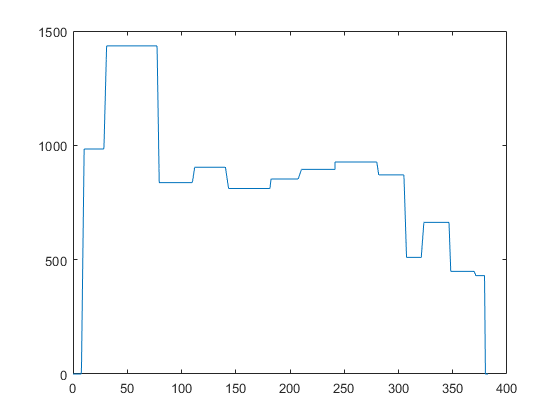

% fullMatFileName = fullfile(folder_data,  'data.mat');
% load(fullMatFileName); % w is loaded (load data)

load load_to_test
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)'/2;
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
% plot(t,w)

## Get the EMS files if needed

% fuzzy_1 = readfis(strcat(projectpath,'\EMS\fuzzy_1.fis'));
set_param('powertrain/EMS/Management Variant/FUZZY/Fuzzy Logic Controller','FIS',"'fuzzy_1.fis'");

## Set data

Ts = 1e-3;
SimTime = 85; % Max simulation time

% set the initial battery SOC
SOC_init = 80;
set_param('powertrain/Battery','SOC', string(SOC_init));
EMS_block  = 'powertrain/EMS';
warning('off','all');

## Start the different simulations

### **PI (~100% of SimTime)**

% tic
% close all;
% warning('off','all')
% set_param(EMS_block,'ems','PI');
% PI = sim(model,'StartTime','0','StopTime',num2str(SimTime));
% % save_(PI,folder_data,SOC_init,'PI',SimTime);
% PI.real_time_sim = toc;

### SMC** (60% of SimTime)**

% tic
% % clear out;
% set_param(EMS_block,'ems','SMC');
% SMC = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');
% % save_(outSMC,folder_data,SOC_init,'SMC',SimTime);
% SMC.real_time_sim = toc;

### FUZZY** (75% of SimTime)**

% tic
% % clear out;
% set_param(EMS_block,'ems','FUZZY');
% warning('off','all');
% % fuzzy_1 = readfis(strcat(projectpath,'\EMS\fuzzy_1.fis'));
% FUZZY = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


C_sc = 1

% % save_(FUZZY,folder_data,SOC_init,'FUZZY',SimTime);
% FUZZY.real_time_sim = toc;

### ECMS** (400% of SimTime)**

tic
% clear out;
set_param(EMS_block,'ems','ECMS');
ECMS = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


% save_(ECMS,folder_data,SOC_init,'ECMS',SimTime);
ECMS.real_time_sim = toc;

### EEMS** (115% of SimTime)**

% tic
% % clear out;
% set_param(EMS_block,'ems','EEMS');
% EEMS = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');
% % save_(EEMS,folder_data,SOC_init,'ECMS',SimTime);
% EEMS.real_time_sim = toc;

### D-ECMS** (400% of SimTime)**

% tic
% % clear out;
% set_param(EMS_block,'ems','D-ECMS');
% DECMS = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');
% % save_(DECMS,folder_data,SOC_init,'ECMS',SimTime);
% DECMS.real_time_sim = toc;

## Save (Don't use it if you don't want to save the data)

% tic 
% save_(PI,folder_data,SOC_init,'PI',SimTime);
% save_(SMC,folder_data,SOC_init,'SMC',SimTime);
% save_(FUZZY,folder_data,SOC_init,'FUZZY',SimTime);
% save_(ECMS,folder_data,SOC_init,'ECMS',SimTime);
% save_(EEMS,folder_data,SOC_init,'EEMS',SimTime);
% save_(DECMS,folder_data,SOC_init,'D-ECMS',SimTime);
% toc
